## IED-TW delay VS  IED-LC delay

clc; clear; close all;
addpath z_toolbox;
load(fullfile('step5_IEDxcorr_polyfit', ...
    'IED6d0_XC100ms_polyfit_delays_Rmax_ED_es.mat'), ...
    'IEDtwDas', 'IEDxcDas');
x = IEDtwDas; y = IEDxcDas;
[forest, ~, scores] = iforest([x, y], "ContaminationFraction", 0.1);
x = x(scores <= forest.ScoreThreshold);
y = y(scores <= forest.ScoreThreshold);
[~, Curve, ~] = f_polyfit(x, y, 1);
[R, P] = corr(x, y, 'type', 'Spearman');
figure('Units', 'centimeters', 'Position', [5, 5, 12, 10]);
f_densityScatter(x, y, 6); hold on;
plot(Curve.x, Curve.y, 'r-', 'LineWidth', 2); hold off;
xlim([min(x)-1, max(x)+1]); ylim([min(y)-1, max(y)+1]);
xlabel('IED-TW Delay (ms)'); ylabel('IED-LC Delay (ms)');
disp(['r=', num2str(R), ' p=', num2str(P)]);

r=0.67698 p=0


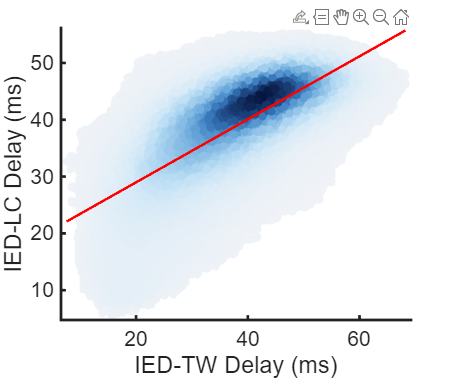

set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);

## Euclidean distance vs. IED-XC delay

clc; close all; clear;
load(fullfile('step5_IEDxcorr_polyfit', ...
    'IED6d0_XC100ms_polyfit_delay_Rmax_ED_as.mat'), 'adjR2_xcDED_as');
[~, order_opt] = max(mean(adjR2_xcDED_as, 1));
load(fullfile('step5_IEDxcorr_polyfit', ...
    'IED6d0_XC100ms_polyfit_delays_Rmax_ED_es.mat'), 'EDas', 'IEDxcDas');
x = EDas; y = IEDxcDas;
[forest, ~, scores] = iforest([x, y], "ContaminationFraction", 0.1);
x = x(scores <= forest.ScoreThreshold);
y = y(scores <= forest.ScoreThreshold);
[polyModel, Curve, Ftest] = f_polyfit(x, y, order_opt);
adjR2 = polyModel.adjR2; Fstat = Ftest.Fstat; P = Ftest.p_value;
figure('Units', 'centimeters', 'Position', [5, 5, 12, 10]);
f_densityScatter(x, y, 2); hold on;
plot(Curve.x, Curve.y, 'r-', 'LineWidth', 2); hold off;
xlim([min(x)-1, max(x)+1]); ylim([min(y)-1, max(y)+1]);
xlabel('Euclidean Distance (mm)'); ylabel('IED-LC Delay (ms)');
disp(['adjR2=', num2str(adjR2), ' F=', num2str(Fstat), ' p=', num2str(P)]);

adjR2=0.29091 F=19784.0162 p=0


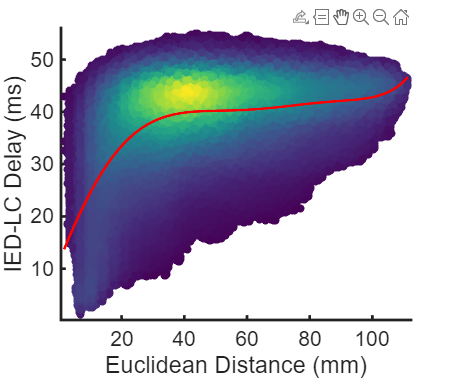

set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);

## IED XC strength vs delays

clc; clear; close all;
load(fullfile('step5_IEDxcorr_polyfit', ...
    'IED6d0_XC100ms_polyfit_delays_Rmax_ED_es.mat'), ...
    'IEDxcRas', 'IEDxcDas');
x = IEDxcRas; y = IEDxcDas;
[forest, ~, scores] = iforest([x, y], "ContaminationFraction", 0.1);
x = x(scores <= forest.ScoreThreshold);
y = y(scores <= forest.ScoreThreshold);
[R, P] = corr(x, y, 'type', 'Spearman');
[~, Curve, ~] = f_polyfit(x, y, 1);
figure('Units', 'centimeters', 'Position', [5, 5, 12, 10]);
f_densityScatter(x, y, 2); hold on;
plot(Curve.x, Curve.y, 'r-', 'LineWidth', 2); hold off;
xlim([min(x)-0.01, max(x)+0.01]); ylim([min(y)-1, max(y)+1]);
xlabel('log(IED-LC Strength)'); ylabel('IED-LC Delay (ms)');
disp(['r=', num2str(R), ' p=', num2str(P)]);

r=-0.47258 p=0


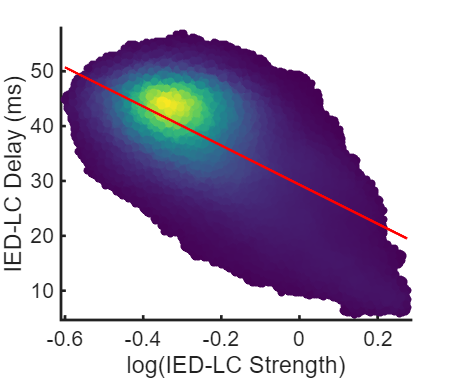

set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);

## Fiber count VS IED XC delays

clc;clear;close all;
load(fullfile('step5_IEDxcorr_polyfit', ...
    'IED6d0_XC100ms_polyfit_delay_fibN.mat'), ...
    'fibNas', 'IEDxcDas')
x = fibNas; y = IEDxcDas;
[forest, tf, scores] = iforest([x, y], "ContaminationFraction", 0.1);
x = x(scores <= forest.ScoreThreshold);
y = y(scores <= forest.ScoreThreshold);
[R, P] = corr(x, y, 'type', 'Spearman');
[polyModel, Curve, Ftest] = f_polyfit(x, y, 1);
figure('Units', 'centimeters', 'Position', [5, 5, 12, 10]);
f_densityScatter(x, y, 2); hold on;
plot(Curve.x, Curve.y, 'r-', 'LineWidth', 2); hold off;
xlim([min(x)-0.1, max(x)+0.1]); ylim([min(y)-1, max(y)+1]);
xlabel('SC Strength'); ylabel('IED-LC Delay (ms)');
disp(['r=', num2str(R), ' p=', num2str(P)]);

r=-0.28101 p=0


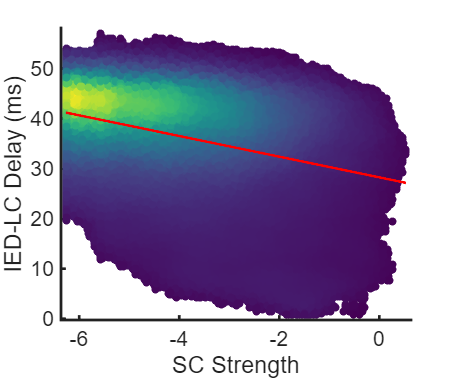

set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);